# Informe de avance de desarrollo mediante Live Script

El siguiente es un ejemplo de cómo utilizar el **live script **para acelerar la programación exploratoria. De esta manera podremos:

- Consultar código y resultados.

- Dividir el programa en secciones a evaluar individualmente bloques de código (subprocesos).

- Incluir visualizaciones, que no necesariamente formen parte del código final, sino a fines de la exploración de los datos.

- Experimentar con valores de parámetro mediante controles.

- Resumir y compartir los resultados previos.

De ninguna pretende ser el live script un producto final, sino más bien una herramienta de testeo y documentación. 

## **Cargar los datos de accidentes mortales en ruta**

Para ejecutar una sección,** Run Section**. 

En este ejemplo, exploramos algunos datos de accidentes mortales. Primer paso carga de los datos. Las variables aparecen como encabezados de las columnas de la tabla.

load fatalities
fatalities(1:10,:)

ans =                             longitude    latitude    deaths    drivers    vehicles    vehicleMiles    alcoholRelated    urbanPopulation
                            _________    ________    ______    _______    ________    ____________    ______________    _______________

    Wyoming                 -107.56      43.033      164       380.18     671.53       9261            54               65.226         
    District_of_Columbia    -77.027      38.892       43       349.12      240.4       3742            12                  100         
    Vermont                 -72.556      44.043       98       550.46     551.52       7855            20               38.196

## **Calcular las tasas de mortalidad**

Podemos dividir un programa en secciones (subprocesos) que contienen texto, código y salida. Para crear una nueva sección, **Section Break**. El código en una sección puede funcionar independientemente, lo que facilita explorar ideas nuevas. En produccion estas secciones tomaran la forma de funciones. 

Calcular la tasa de letalidad por 1 millón millas. De estos valores podemos encontrar los Estados con las tasas de mortalidad más bajo y más alto.

states = fatalities.Properties.RowNames;
rate = fatalities.deaths./fatalities.vehicleMiles;
[~, minIdx] = min(rate);                  % Minimum accident rate
[~, maxIdx] = max(rate);                  % Maximum accident rate
disp([states{minIdx} ' has the lowest fatality rate at ' num2str(rate(minIdx))])

Massachusetts has the lowest fatality rate at 0.0086907


disp([states{maxIdx} ' has the highest fatality rate at ' num2str(rate(maxIdx))])

Mississippi has the highest fatality rate at 0.022825


**Distribución de las muertes**

Se puede incluir visualizaciones, ya sean imagenes, figuras o diagramas. 

Podemos utilizar un gráfico de barras para ver la distribución de las tasas de mortalidad entre los Estados. Hay 11 Estados que tienen una tasa de letalidad superior a 0.02 por millones millas.

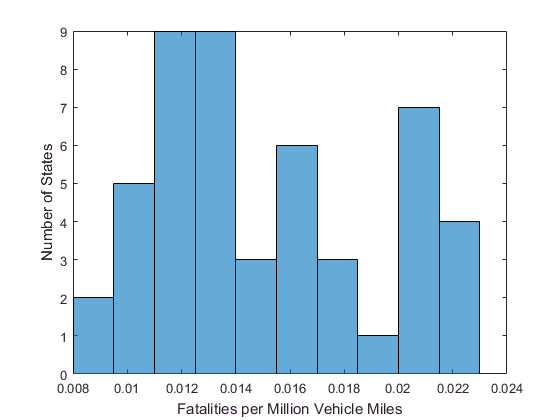

histogram(rate,10)
xlabel('Fatalities per Million Vehicle Miles')
ylabel('Number of States')

## **Encontrar correlaciones en los datos**

Explorar los datos rápidamente, nos permite ir experimentando con valores de parámetro para ver cómo va a cambiar los resultados. En este caso, podemos experimentar con los datos para ver si cualquiera de las variables en  la tabla se correlacionan con accidentes mortales en ruta. Por ejemplo, parece que las tasas de letalidad en ruta son más bajas en Estados con una mayor población urbana porcentaje.

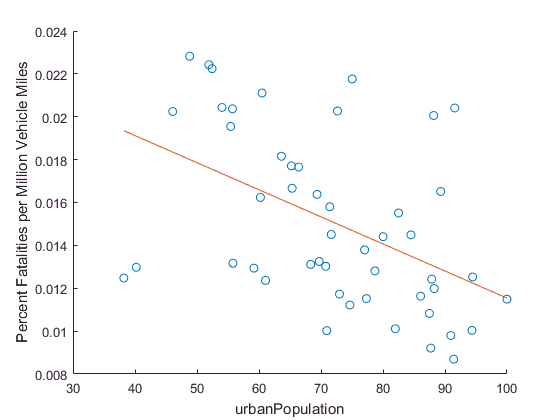

dataToPlot = 'urbanPopulation';
close                                      % Close any open figures
scatter(fatalities.(dataToPlot),rate)         % Plot fatalities vs. selected variable
xlabel(dataToPlot)
ylabel('Percent Fatalities per Million Vehicle Miles') 

hold on
xmin = min(fatalities.(dataToPlot));
xmax = max(fatalities.(dataToPlot));
p = polyfit(fatalities.(dataToPlot),rate,1);  % Calculate & plot least squares line
plot([xmin xmax], polyval(p,[xmin xmax]))